dataimporter;


means = [];
stds = [];

percentage = 30;

[training_datain,validation_datain] = holdback(datain,percentage);

% extract feature and response data
[training_full, ~, num_features] = combined_feature_tabler(training_datain);
[validation_full, ~, ~] = combined_feature_tabler(validation_datain);



# Regression Network Preamble

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(5)
    reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
 

xtr = table2array(training_full(:,1:num_features));
ytr = table2array(training_full(:,end));

xvr = table2array(validation_full(:,1:num_features));
yvr = table2array(validation_full(:,end));

yvr = nan_checker(yvr);
ytr = nan_checker(ytr);

%nan correction
xtr(isnan(xtr)) = 0;
xvr(isnan(xvr)) = 0;

## Regression Netowork Training

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |         1.00 |         1.00 |       0.5008 |       0.4990 |          0.0020 |
|       1 |          25 |       00:00:05 |         0.98 |         0.95 |       0.4831 |       0.4519 |          0.0020 |
|       2 |          50 |       00:00:08 |         0.91 |         0.85 |       0.4096 |       0.3647 |          0.0020 |
|       3 |          75 |       00:00:10 |         0.82 |         0.77 |       0.3397 |       0.2963 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×1750 double]
           TrainingRMSE: [1×1750 double]
         ValidationLoss: [1×1750 double]
         ValidationRMSE: [1×1750 double]
          BaseLearnRate: [1×1750 double]
    FinalValidationLoss: 0.1871
    FinalValidationRMSE: 0.6118


hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 15.9544
        std_predicted: 34.0718
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 59
          correct_271: 145
             beat_271: 322
    default_hd_picked: 17
        max_predicted: 286.8549
              max_271: 346.8545


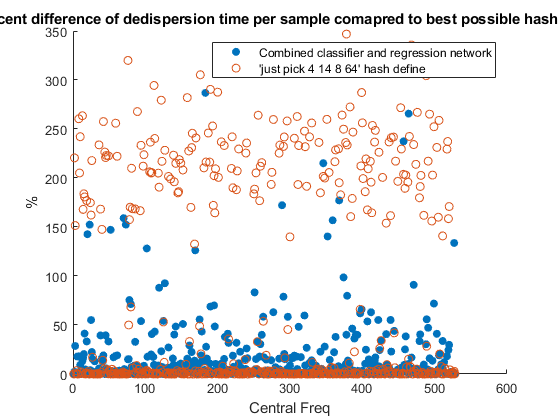

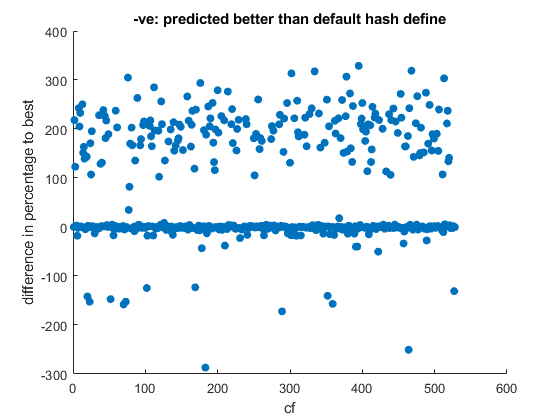

means(1) = reg_stats.mean_predicted;
stds(1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(5)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         0.99 |         1.00 |       0.4907 |       0.5008 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.95 |         0.94 |       0.4522 |       0.4403 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.84 |         0.80 |       0.3521 |       0.3224 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.76 |         0.71 |       0.2897 |       0.2538 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×650 double]
           TrainingRMSE: [1×650 double]
         ValidationLoss: [1×650 double]
         ValidationRMSE: [1×650 double]
          BaseLearnRate: [1×650 double]
    FinalValidationLoss: 0.1970
    FinalValidationRMSE: 0.6277



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 18.8658
        std_predicted: 35.6084
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 48
          correct_271: 145
             beat_271: 316
    default_hd_picked: 19
        max_predicted: 267.8281
              max_271: 346.8545


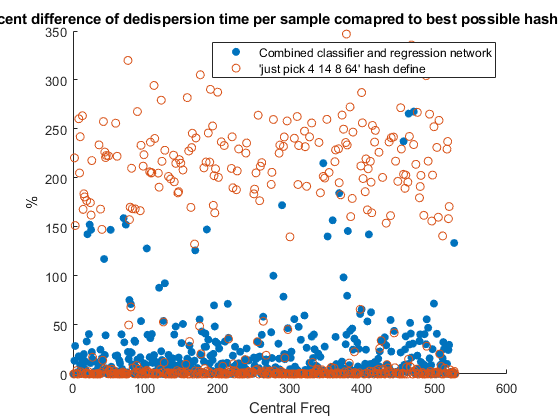

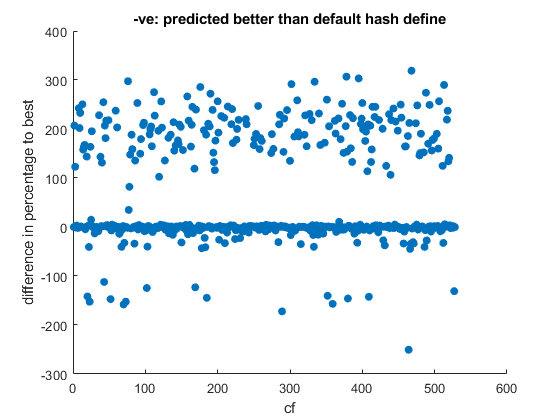

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         0.99 |         1.00 |       0.4933 |       0.4990 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.97 |         0.93 |       0.4751 |       0.4331 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.87 |         0.84 |       0.3778 |       0.3563 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.79 |         0.75 |       0.3090 |       0.2806 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×1150 double]
           TrainingRMSE: [1×1150 double]
         ValidationLoss: [1×1150 double]
         ValidationRMSE: [1×1150 double]
          BaseLearnRate: [1×1150 double]
    FinalValidationLoss: 0.1833
    FinalValidationRMSE: 0.6054



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 15.8612
        std_predicted: 34.8452
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 61
          correct_271: 145
             beat_271: 315
    default_hd_picked: 14
        max_predicted: 275.9480
              max_271: 346.8545


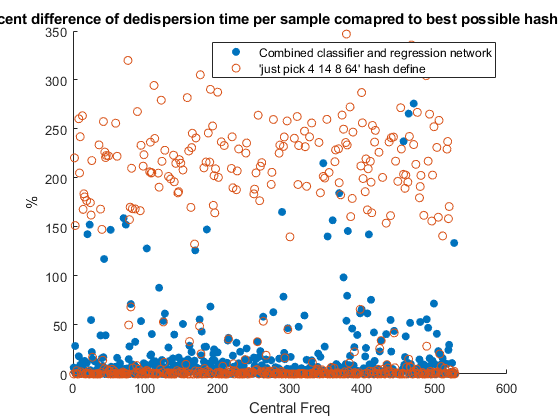

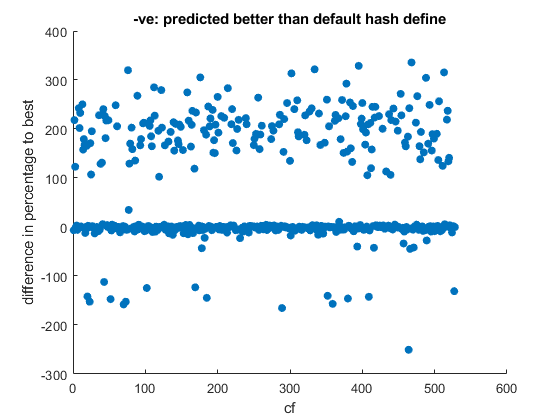

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.00 |         1.00 |       0.5010 |       0.5000 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.98 |         0.96 |       0.4809 |       0.4638 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.90 |         0.83 |       0.4025 |       0.3427 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.79 |         0.72 |       0.3086 |       0.2597 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×700 double]
           TrainingRMSE: [1×700 double]
         ValidationLoss: [1×700 double]
         ValidationRMSE: [1×700 double]
          BaseLearnRate: [1×700 double]
    FinalValidationLoss: 0.2014
    FinalValidationRMSE: 0.6346



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 16.4845
        std_predicted: 33.7853
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 62
          correct_271: 145
             beat_271: 324
    default_hd_picked: 12
        max_predicted: 326.4931
              max_271: 346.8545


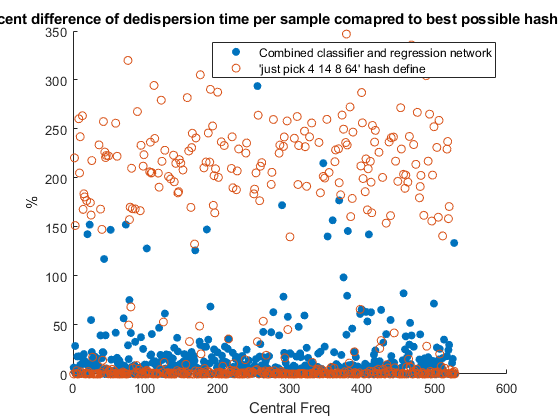

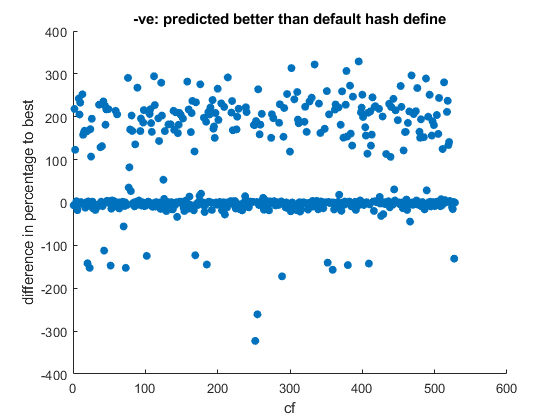

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.12 |         1.00 |       0.6250 |       0.4972 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.99 |         1.00 |       0.4918 |       0.4961 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.98 |         0.97 |       0.4830 |       0.4740 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.91 |         0.88 |       0.4127 |       0.3876 |          0.0020 |
|       


hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 15.0308
        std_predicted: 30.5296
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 57
          correct_271: 145
             beat_271: 324
    default_hd_picked: 11
        max_predicted: 236.8560
              max_271: 346.8545


means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

|      45 |        1475 |       00:03:01 |         0.63 |         0.60 |       0.1955 |       0.1792 |          0.0020 |
|      46 |        1500 |       00:03:04 |         0.62 |         0.60 |       0.1944 |       0.1808 |          0.0020 |
|      47 |        1525 |       00:03:07 |         0.65 |         0.60 |       0.2131 |       0.1802 |          0.0020 |
|      47 |        1550 |       00:03:10 |         0.63 |         0.60 |       0.1975 |       0.1792 |          0.0020 |
|      48 |        1575 |       00:03:13 |         0.64 |         0.60 |       0.2043 |       0.1796 |          0.0020 |
|      49 |        1600 |       00:03:16 |         0.62 |         0.60 |       0.1916 |       0.1830 |          0.0020 |
|======================================================================================================================|


rnet =   SeriesNetwork with properties:

         Layers: [20×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×1600 double]
           TrainingRMSE: [1×1600 double]
         ValidationLoss: [1×1600 double]
         ValidationRMSE: [1×1600 double]
          BaseLearnRate: [1×1600 double]
    FinalValidationLoss: 0.1830
    FinalValidationRMSE: 0.6050



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 15.9204
        std_predicted: 32.6963
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 58
          correct_271: 145
             beat_271: 316
    default_hd_picked: 9
        max_predicted: 267.8281
              max_271: 346.8545


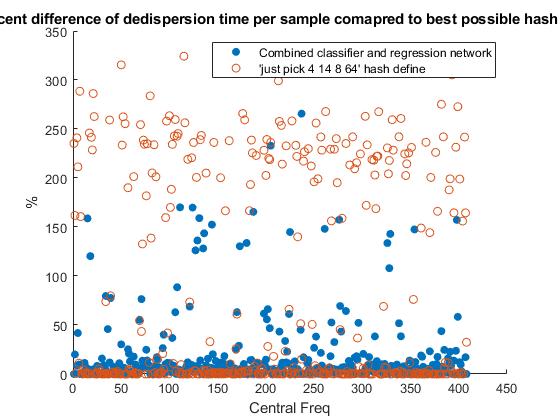

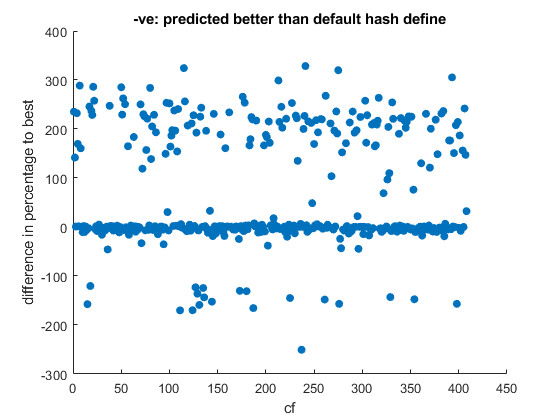

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(30)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(20)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.08 |         1.00 |       0.5882 |       0.4988 |          0.0020 |
|       1 |          25 |       00:00:04 |         0.99 |         1.00 |       0.4941 |       0.4988 |          0.0020 |
|       2 |          50 |       00:00:07 |         1.00 |         1.00 |       0.5038 |       0.4982 |          0.0020 |
|       3 |          75 |       00:00:10 |         0.99 |         1.00 |       0.4936 |       0.4985 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [20×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×1850 double]
           TrainingRMSE: [1×1850 double]
         ValidationLoss: [1×1850 double]
         ValidationRMSE: [1×1850 double]
          BaseLearnRate: [1×1850 double]
    FinalValidationLoss: 0.2055
    FinalValidationRMSE: 0.6411



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 43.2968
        std_predicted: 40.0602
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 5
          correct_271: 145
             beat_271: 312
    default_hd_picked: 1
        max_predicted: 267.8281
              max_271: 346.8545


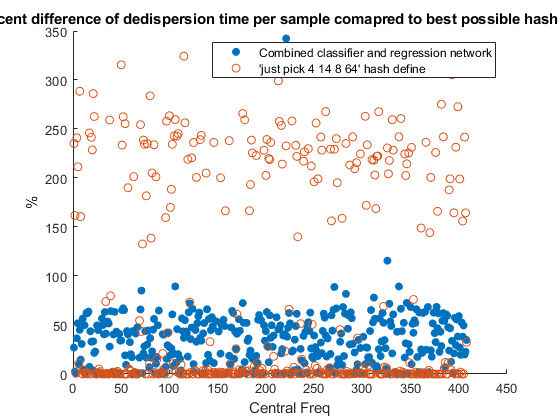

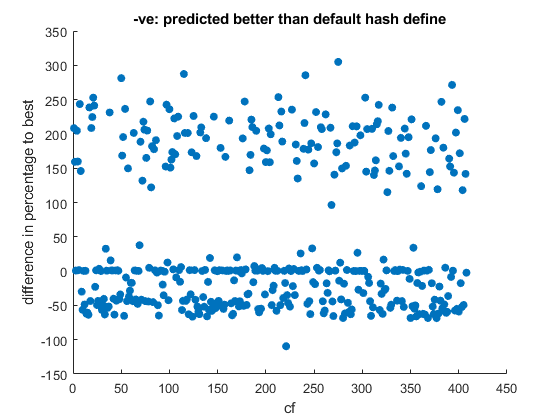

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(30)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(30)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(20)
    leakyReluLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         1.04 |         1.00 |       0.5447 |       0.5018 |          0.0020 |
|       1 |          25 |       00:00:04 |         0.98 |         0.99 |       0.4755 |       0.4937 |          0.0020 |
|       2 |          50 |       00:00:07 |         0.95 |         0.93 |       0.4524 |       0.4368 |          0.0020 |
|       3 |          75 |       00:00:10 |         0.92 |         0.86 |       0.4193 |       0.3720 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [18×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×650 double]
           TrainingRMSE: [1×650 double]
         ValidationLoss: [1×650 double]
         ValidationRMSE: [1×650 double]
          BaseLearnRate: [1×650 double]
    FinalValidationLoss: 0.2097
    FinalValidationRMSE: 0.6476



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 15.8560
        std_predicted: 33.6917
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 66
          correct_271: 145
             beat_271: 304
    default_hd_picked: 10
        max_predicted: 267.8281
              max_271: 346.8545


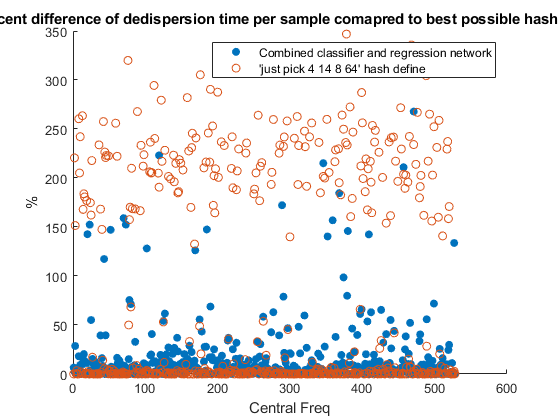

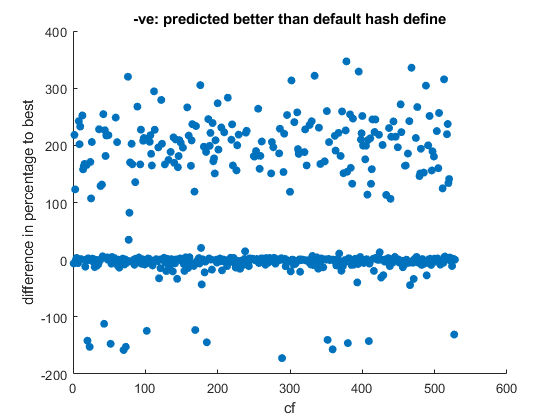

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.03 |         1.00 |       0.5310 |       0.4960 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.96 |         0.94 |       0.4609 |       0.4383 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.85 |         0.83 |       0.3647 |       0.3446 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.78 |         0.73 |       0.3043 |       0.2673 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×350 double]
           TrainingRMSE: [1×350 double]
         ValidationLoss: [1×350 double]
         ValidationRMSE: [1×350 double]
          BaseLearnRate: [1×350 double]
    FinalValidationLoss: 0.2403
    FinalValidationRMSE: 0.6933



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 14.4573
        std_predicted: 29.2163
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 63
          correct_271: 145
             beat_271: 313
    default_hd_picked: 23
        max_predicted: 267.8281
              max_271: 346.8545


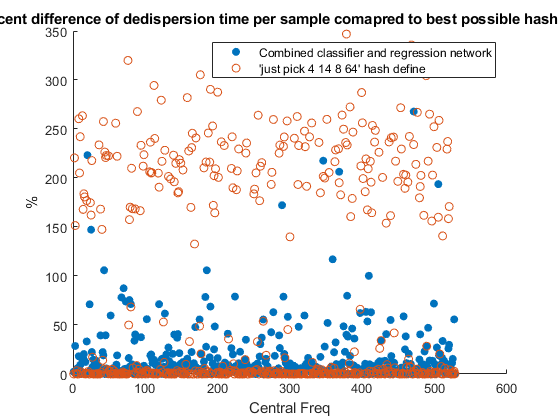

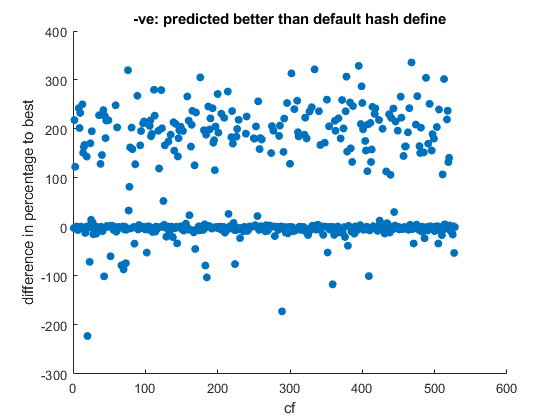

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.00 |         1.00 |       0.4959 |       0.4985 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.98 |         0.98 |       0.4835 |       0.4775 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.89 |         0.83 |       0.3968 |       0.3460 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.79 |         0.73 |       0.3086 |       0.2672 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×400 double]
           TrainingRMSE: [1×400 double]
         ValidationLoss: [1×400 double]
         ValidationRMSE: [1×400 double]
          BaseLearnRate: [1×400 double]
    FinalValidationLoss: 0.2120
    FinalValidationRMSE: 0.6512



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 18.1186
        std_predicted: 35.4730
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 62
          correct_271: 145
             beat_271: 324
    default_hd_picked: 14
        max_predicted: 326.4931
              max_271: 346.8545


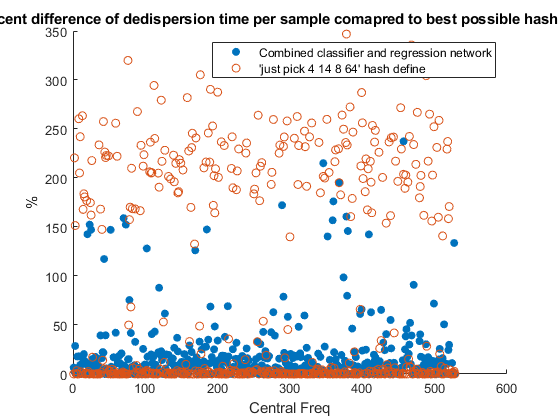

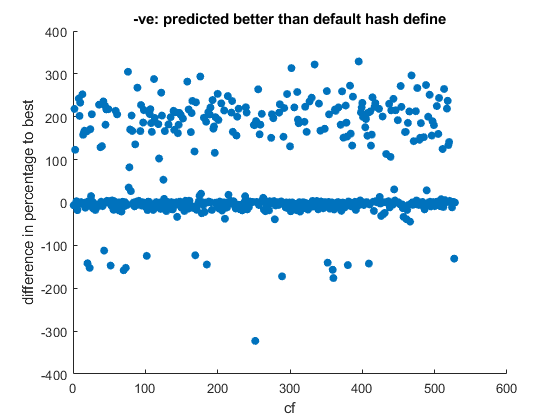

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer
    fullyConnectedLayer(5)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         0.98 |         1.00 |       0.4818 |       0.4961 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.95 |         0.95 |       0.4559 |       0.4496 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.87 |         0.85 |       0.3816 |       0.3609 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.76 |         0.73 |       0.2918 |       0.2650 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×600 double]
           TrainingRMSE: [1×600 double]
         ValidationLoss: [1×600 double]
         ValidationRMSE: [1×600 double]
          BaseLearnRate: [1×600 double]
    FinalValidationLoss: 0.2031
    FinalValidationRMSE: 0.6373



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 16.6671
        std_predicted: 33.5470
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 62
          correct_271: 145
             beat_271: 323
    default_hd_picked: 6
        max_predicted: 267.8281
              max_271: 346.8545


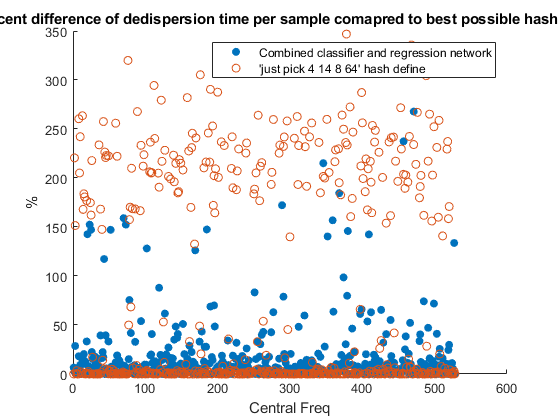

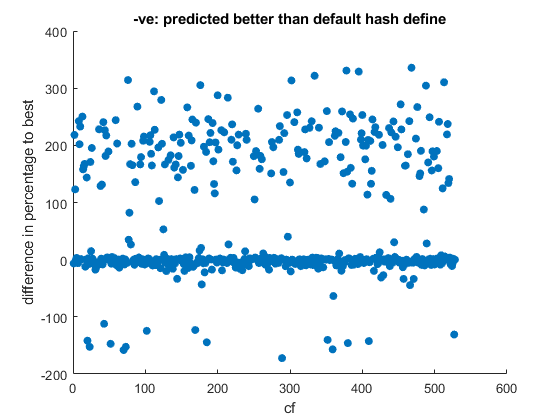

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);

regression_layers = [
    featureInputLayer(num_features)%potential to name input features here if it might help
    fullyConnectedLayer(30)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    dropoutLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    fullyConnectedLayer(20)
    leakyReluLayer
    fullyConnectedLayer(10)
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer];

%plots to 'training-progess'
trainoptsr = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.002,'Plots','none', ...
            'MiniBatchSize',10000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xvr,yvr}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[rnet, net5info] = trainNetwork(xtr,ytr,regression_layers,trainoptsr)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.06 |         1.02 |       0.5660 |       0.5158 |          0.0020 |
|       1 |          25 |       00:00:03 |         0.97 |         0.97 |       0.4725 |       0.4705 |          0.0020 |
|       2 |          50 |       00:00:06 |         0.91 |         0.85 |       0.4160 |       0.3637 |          0.0020 |
|       3 |          75 |       00:00:09 |         0.80 |         0.77 |       0.3186 |       0.2940 |          0.0020 |
|       

rnet =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net5info = struct with fields:
           TrainingLoss: [1×650 double]
           TrainingRMSE: [1×650 double]
         ValidationLoss: [1×650 double]
         ValidationRMSE: [1×650 double]
          BaseLearnRate: [1×650 double]
    FinalValidationLoss: 0.2012
    FinalValidationRMSE: 0.6344



hd_preds = reg_predictor(rnet,xvr);
reg_stats = location_statter(hd_preds,validation_datain)

reg_stats = struct with fields:
       mean_predicted: 16.3299
        std_predicted: 35.1501
             mean_271: 80.3912
              std_271: 106.9923
        correct_preds: 79
          correct_271: 145
             beat_271: 320
    default_hd_picked: 34
        max_predicted: 293.8190
              max_271: 346.8545


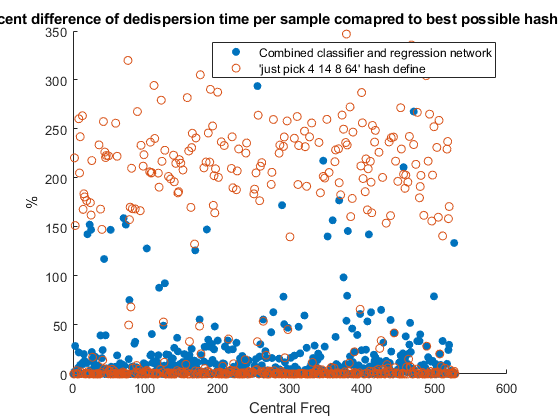

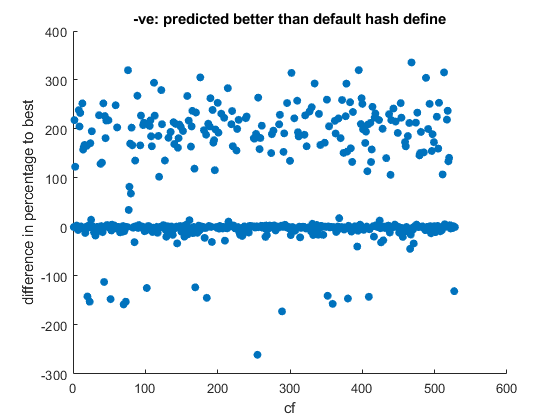

means(end+1) = reg_stats.mean_predicted;
stds(end+1) = reg_stats.std_predicted;
location_plotter(hd_preds,validation_datain);